close all
clear
clc

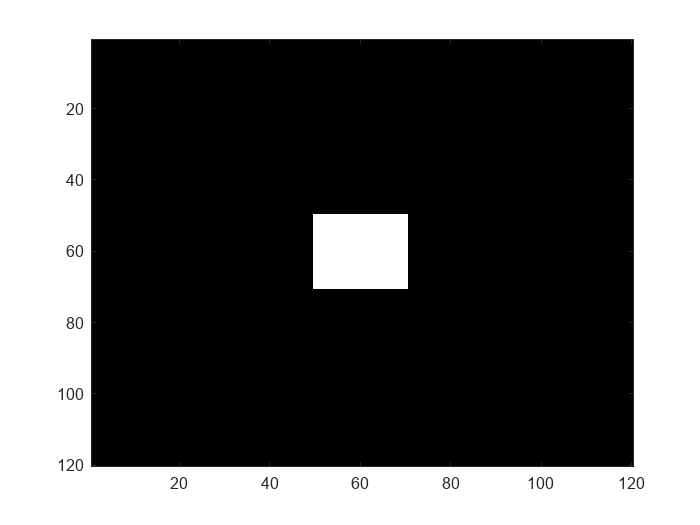

A = zeros(120, 120, 3);
A(size(A)/2-10:size(A)/2+10, size(A)/2-10:size(A)/2+10, :) = 10;
imagesc(A);

x = 60; 
y = 60; 
z = 2;

Blocco per settare i valori iniziali dell'evoluzione.


N_start = 27;  % Numero iniziale di formiche
Ant(1:N_start) = ant;
init_voxel = [x, y, z];
Cell_voxel_count = [];  % Matrice le cui righe sono le coordinate di ogni voxel visitato
Coordinates = initialize_coordinates(A, N_start, x, y, z);
pheromone_map = initialize_pheromone_map(A);
pheromone = [];
Cell_num_cycle = {N_start; 0};  % Cella che conserva il numero di formiche ed il numero del ciclo
e_death = 1;
e_reproduction = 1.3;

Inizializza le coordinate delle formiche, marca ogni voxel e vi rilascia il feromone.

for i=1:N_start
    Ant(i).x = Coordinates(i, 1);
    Ant(i).y = Coordinates(i, 2);
    Ant(i).z = Coordinates(i, 3);
    pheromone_map(Ant(i).x, Ant(i).y, Ant(i).z, 2) = Ant.mark_voxel();
    pheromone_map(Ant(i).x, Ant(i).y, Ant(i).z, 1) = pheromone_map(Ant(i).x, Ant(i).y, Ant(i).z, 1) + Ant(i).pheromone_release(A);
end

tic
cycles = 1;
N = N_start;
while cycles < 50
    j = 1;
    while j <= length(Ant)
        Cell_voxel_count = [Cell_voxel_count; [Ant(j).x, Ant(j).y, Ant(j).z]];
        pheromone = [pheromone, Ant(j).pheromone_release(A) - Ant(j).eta];
        Ant(j).energy = Ant(j).update_energy(pheromone(j), sum(pheromone)/numel(pheromone));
        if Ant(j).energy < e_death
            Ant(j) = [];
            N = N - 1;
            if N<1
                break;
            end
            continue
        elseif Ant(j).energy > e_reproduction
            Ant(j).energy = 1.2;
            Daughter_ant = ant;
            Daughter_ant.x = Ant(j).x;
            Daughter_ant.y = Ant(j).y;
            Daughter_ant.z = Ant(j).z;
            next_voxel = Daughter_ant.evaluate_destination(0, pheromone_map);
            if isempty(next_voxel)==1
                Daughter_ant = [];
            else
                Daughter_ant.x = next_voxel(1);
                Daughter_ant.y = next_voxel(2);
                Daughter_ant.z = next_voxel(3);
                pheromone_map(Daughter_ant.x, Daughter_ant.y, Daughter_ant.z, 2) = Daughter_ant.mark_voxel();
                pheromone_map(Daughter_ant.x, Daughter_ant.y, Daughter_ant.z, 1) = pheromone_map(Daughter_ant.x, Daughter_ant.y, Daughter_ant.z, 1) + Daughter_ant.pheromone_release(A);
                Ant = [Ant, Daughter_ant];
                N = N + 1;
            end
        end

        j = j + 1;
    end
    if N < 1
        disp('Nessuna formica rimasta')
        break;
    end
    j = 1;
    while j <= length(Ant)
        next_voxel = Ant(j).evaluate_destination(0, pheromone_map);
        if isempty(next_voxel) == 1
            %disp('Nessun voxel disponibile, morte della formica')
            pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 2) = Ant.leave_voxel();            
            Ant(j) = [];
            N = N - 1;
            if N<1
                break;
            end
            continue
        else
            pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 2) = Ant.leave_voxel();
            Ant(j).x = next_voxel(1);
            Ant(j).y = next_voxel(2);
            Ant(j).z = next_voxel(3);
            pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 2) = Ant.mark_voxel();
            pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 1) = pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 1) + Ant(j).pheromone_release(A);
        end
        
        j = j + 1;
    end
    if N < 1
        disp('Nessuna formica rimasta_1')
        break;
    elseif N > 8000
        disp('Troppe formiche')
        break;
    end
    cycles = cycles + 1;
    Cell_num_cycle{1} = [Cell_num_cycle{1}, N];
    Cell_num_cycle{2} = [Cell_num_cycle{2}, cycles];
    
end
   

toc

Elapsed time is 6.962979 seconds.


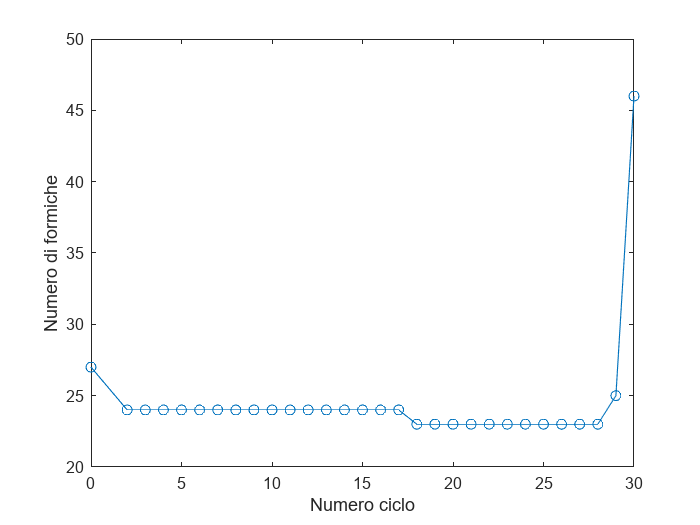

plot(Cell_num_cycle{2, :}, Cell_num_cycle{1, :}, marker = 'o', linestyle = '-')
xlabel('Numero ciclo')
ylabel('Numero di formiche')

[Mu,ia,ic] = unique(Cell_voxel_count, 'rows', 'stable');
h = accumarray(ic, 1);                              % Count Occurrences
maph = h(ic);                                       % Map Occurrences To ‘ic’ Values
Result = [Cell_voxel_count, maph];


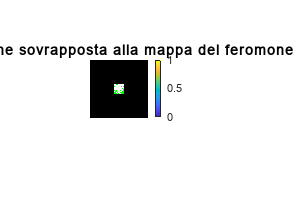

PM = pheromone_map(:, :, :, 1);
imshowpair(A,PM), colorbar;
title('Immagine sovrapposta alla mappa del feromone')

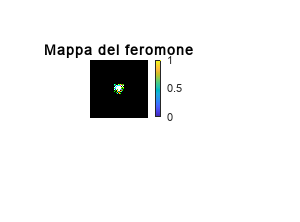

imshow(PM), colorbar;
title('Mappa del feromone')

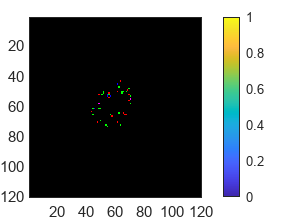

%orthosliceViewer(PM);
imagesc(pheromone_map(:, :, :, 2)), colorbar;

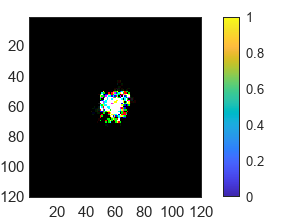

imagesc(10*PM(:, :, :)), colorbar;